What is rotation?

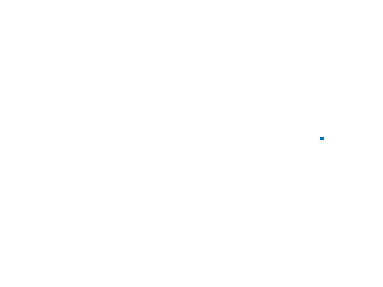

figure

for t=0:pi/36:6*pi
    x=real(exp(1i*t));
    y=imag(exp(1i*t));
    plot(x,y,'.')
    axis([-1.2 1.2 -1.2 1.2])
    axis off
    pause(.05)
end

Let us see the shape of this behaviour

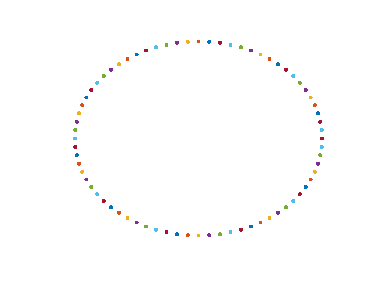

figure
hold on
for t=0:pi/36:6*pi
    x=real(exp(1i*t));
    y=imag(exp(1i*t));
    plot(x,y,'.')
    axis([-1.2 1.2 -1.2 1.2])
    axis off
    pause(.05)
end
hold off

This is the shape of the rotation. Inside of this there is a point that has the same distance from all of the points which is the center.

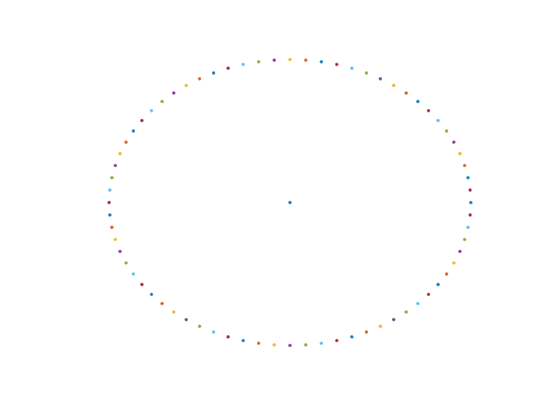

figure
plot(0,0,'.')
hold on
for t=0:pi/36:6*pi
    x=real(exp(1i*t));
    y=imag(exp(1i*t));
    plot(x,y,'.')
    axis([-1.2 1.2 -1.2 1.2])
    axis off
    pause(.05)
end
hold off

Let us draw two orthogonal lines which are intersected at this point

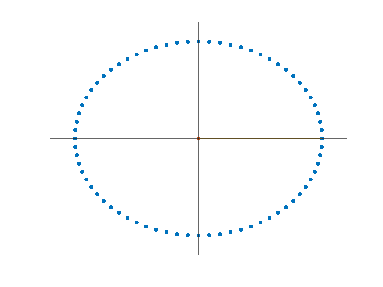

figure


for t=0:pi/36:6*pi
    tt=0:pi/36:t;
    xx=real(exp(1i*tt));
    yy=imag(exp(1i*tt));
    plot(xx,yy,'.')
    hold on
    plot(0,0,'.')
    yline(0)
    xline(0)
    x=real(exp(1i*t));
    y=imag(exp(1i*t));
    plot([0 x],[0 y])
    axis([-1.2 1.2 -1.2 1.2])
    axis off
    pause(.05)
    hold off
end

Assume its radius is r then its circumference is $2\pi r$ so it is (circle)*r then circle=$2\pi$$\rightarrow$half a circle is $\pi$

So we can label any portion of the circle with a fraction of $2\pi$. Let us label it abstracly as $\theta$, so $\theta$ represents a portion of the circle and a rotation. If we add 2 portions of a circle we will get another portion $(\theta_1+\theta_2=\theta_{1+2})$  

z=1i+1

z = 1.0000 + 1.0000i

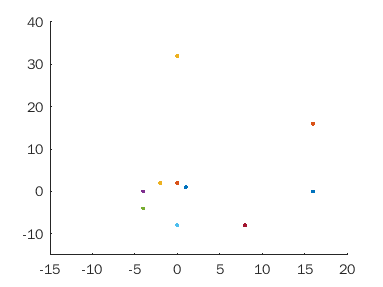

k=1;
figure 
hold on
for ii=1:10
    k=z*k;
    x=real(k);
    y=imag(k);
    plot(x,y,'.')
    axis([-15 20 -15 40])
    pause(.5)
end
hold off

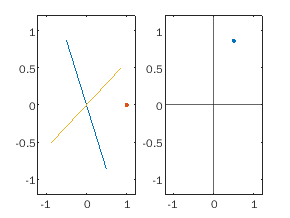

figure
x=1;
xx=1;
y=1i;
t=pi/36;
for k=1:60
        subplot(1,2,1)
        x=exp(1i*t)*x;
        plot([-real(x) real(x)],[-imag(x) imag(x)])
        hold on
        plot(1,0,'.')
        y=exp(1i*t)*y;
        plot([-real(y) real(y)],[-imag(y) imag(y)])
        axis([-1.2 1.2 -1.2 1.2])
        hold off
        subplot(1,2,2)
        xx=exp(-1i*t)*xx;
        plot(real(xx),imag(xx),'.')
        hold on
        xline(0)
        yline(0)
        axis([-1.2 1.2 -1.2 1.2])
        pause(.5)
        hold off
    
end

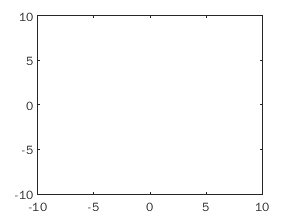

figure
p=1i+.1;
G=exp(p);
GG=exp(p);
for k=1:30
    plot(real(G),imag(G),'.')
    axis([-10 10 -10 10])
    pause(.5)
    G=GG*G;
end